# Using the git version control:

Git version control provides an easy way to keep track of line by line changes over time. Git is a widely used VCS in software industry. MATLAB also supports git VCS to keep track of changes not only in .m files but also in app files and simulink models.

To use git on MATLAB on Windows, install git for windows. Then set up the git for matlab to treat matlab files as binary files (see ['Set Up Git Source Control'](matlab:doc('Set Up Git Source Control')))

To check if matlab can recognize git, run this in command window:

!git -v

git version 2.41.0.windows.1


If matlab can run git, current version of git will be displayed in command window.

After done with setting up, you can create local repository.

## Creating repository:

In matlab, navigate to the folder where you want to place the repository. Right Click the white space in project explorer and select Source Control>manage files.

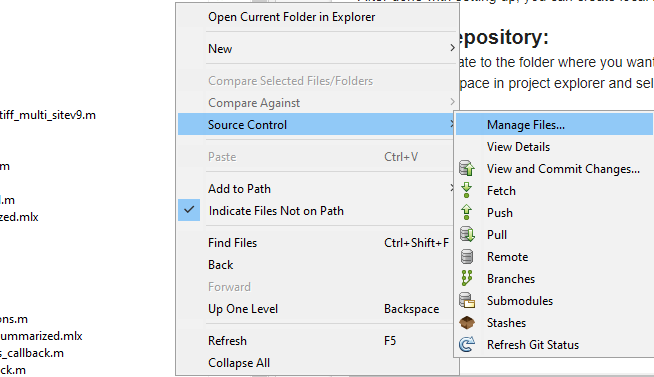

In the 'Manage Files Using Source Control' Dialog box, click 'Change' button to select the path where repository will be created. In the next dialog box, click the '+' button to select path for repository and click validate to check if path is valid.

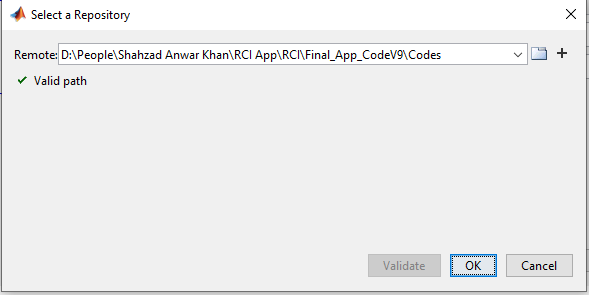

Back in the 'Manage Files..' dialog box, select the 'sandbox' path. This path will be where you place the files to track using git. The recommendation is to make a new folder at the path where you created repository in above step(In git, such a folder is called working directory)

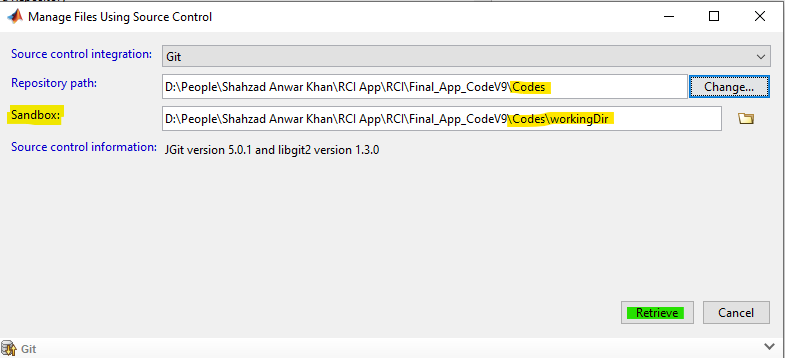

After selection of paths for repository and the sandbox, click retrieve to create the repository. Check if .gitattributes file is created in the project explorer. If no such file is created, run the following command to let git treat matlab files as binaries:

copyfile(fullfile(matlabroot,'toolbox','shared','cmlink','git','auxiliary_files', ...
    'mwgitattributes'),fullfile(pwd,'.gitattributes'))

## Adding Files for tracking

Now, you will create your new files in the working directory of repository. If you want to add files you already have, copy those files to this working directory folder. In matlab, in the project explorer, right click a file and select "**Source Control>Add to Git" **to start tracking changes in the file. You can select multiple files and add them to git.

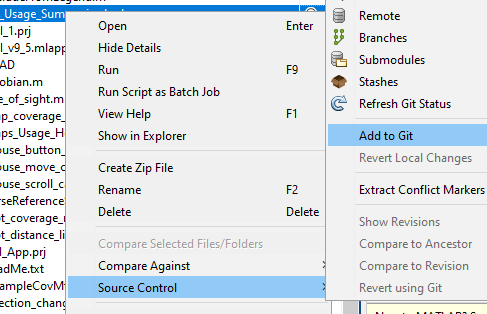

When files have been added to git, matlab shows green circle aggaints such files to show that these files are being tracked. A dot shows that these files can't be added to git(their name added to .gitignore file). A white circle shows that the file has not been added to git for tracking but it can be added to git. A blue square shows that the file has been modified and is now different from its previous version.

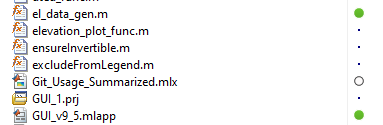

To prevent matlab from adding files that are not already added to git, add a .gitignore file in the working directory and then add all the filenames with extensions which you want to prevent from adding to git

 ---> 

Note that you will need to add the '.gitignore' file to git for tracking, so that it always moves with the repository.

## Saving changes to repository(Commiting):

After setting up files, right click the white space and select "Source Control>View and Commit changes"

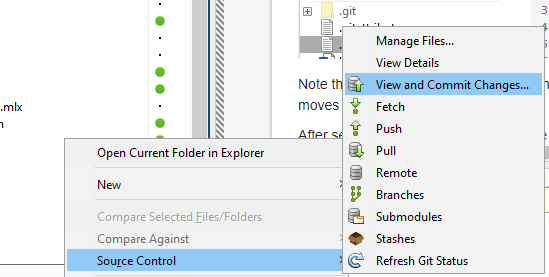

In the dialog box, select the file changes which you want to save to repository, add a comment about these changes and then click commit. After commiting, the blue squares will turn to green circles for the files which you committed.

Learn more ['use git in matlab'](matlab: doc('Use Git in MATLAB')) in help.